HW3 Question 2

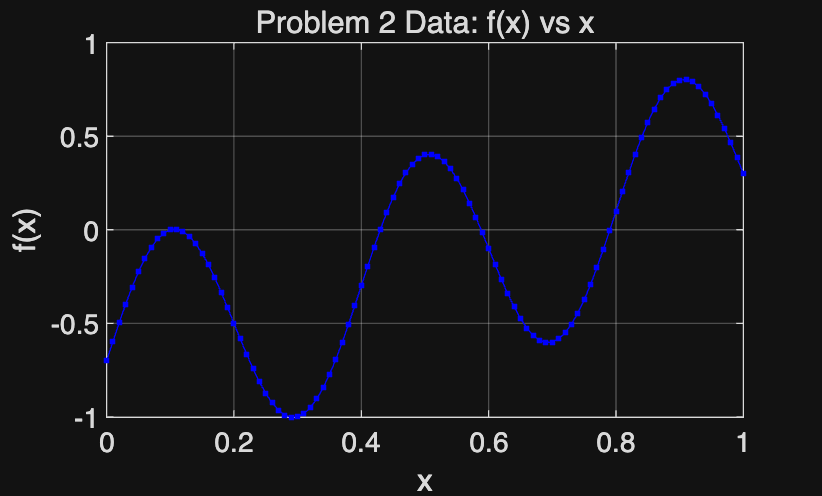

clear; clc; close all;


x = 0:0.01:1;                
y = load("problem2.txt"); 
y = y(:);                    
N = numel(y);
assert(numel(x) == N, 'x and y must have the same length (101).');


figure(1);
plot(x, y, 'b.-');
xlabel('x'); ylabel('f(x)');
title('Problem 2 Data: f(x) vs x');
grid on;

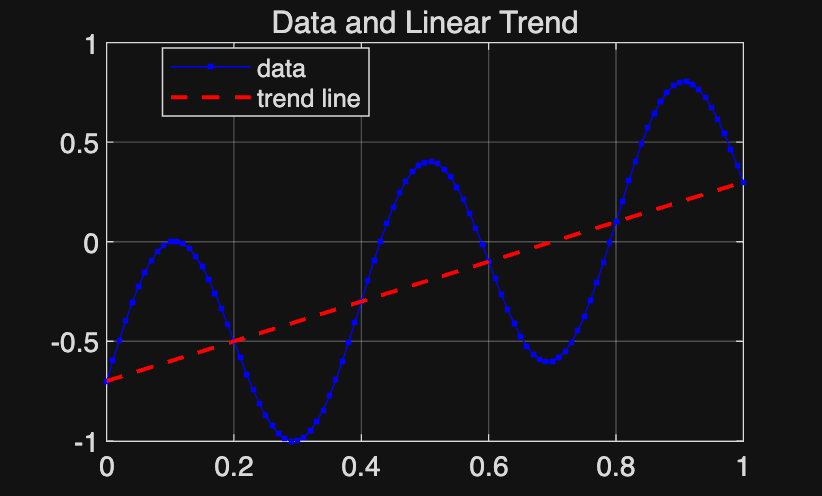



y0 = y(1);
y1 = y(end);
g = (y1 - y0) * x + y0;      

figure(2);
plot(x, y, 'b.-'); hold on;
plot(x, g, 'r--', 'LineWidth', 1.5);
legend('data', 'trend line', 'Location', 'best');
title('Data and Linear Trend');
grid on;

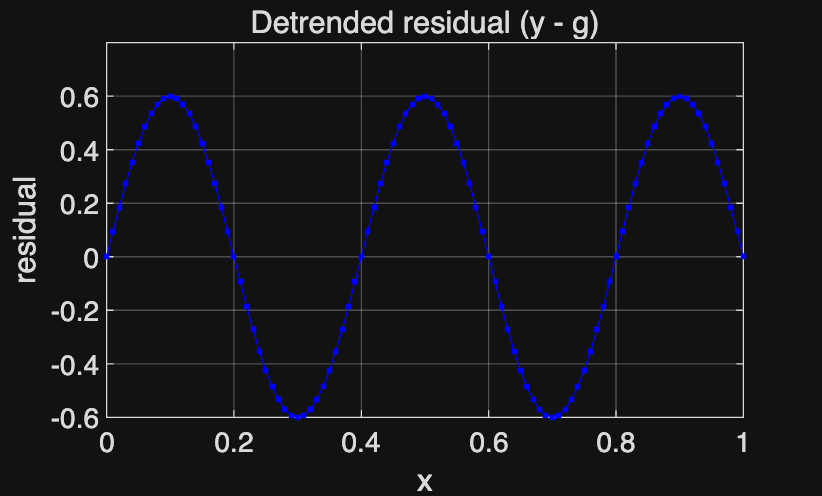



t = y - g.';               
figure(3);
plot(x, t, 'b.-');
xlabel('x'); ylabel('residual');
title('Detrended residual (y - g)');
grid on;

Now we need to approximate the curve. Since the curve has 2.5 period in the range, we could pick k =2.5

k = 2.5;
Ak = [cos(2*pi*k*x(:)), sin(2*pi*k*x(:))];  
beta = (Ak.'*Ak) \ (Ak.'*t);                
bc = beta(1); 
bs = beta(2);


yhat = g.' + Ak*beta;                       


a0 = y(1);                 
a1 = y(end) - y(1);        
fprintf('k  = %.3f\n', k);

k  = 2.500


fprintf('a0 = %11.4e\n', a0);

a0 = -7.0000e-01


fprintf('a1 = %11.4e\n', a1);

a1 =  1.0000e+00


fprintf('bc = %11.4e\n', bc);

bc = -5.4530e-17


fprintf('bs = %11.4e\n', bs);

bs =  6.0000e-01



res = y - yhat;
mse = mean(res.^2);
R2  = 1 - sum(res.^2)/sum((y-mean(y)).^2);
fprintf('MSE = %.4e,   R^2 = %.6f\n', mse, R2);

MSE = 3.3357e-31,   R^2 = 1.000000


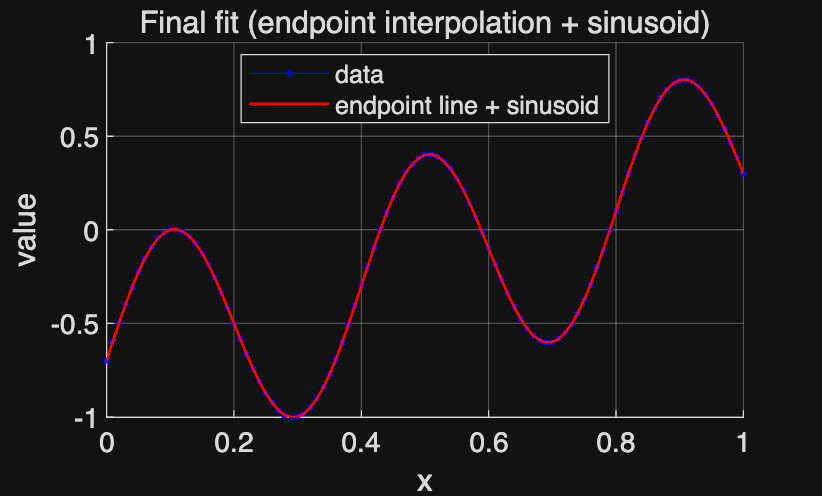


figure; hold on; grid on;
plot(x, y, 'b.-', 'DisplayName','data');
plot(x, yhat, 'r-', 'LineWidth', 1.0, 'DisplayName','endpoint line + sinusoid');
legend('Location','best');
xlabel('x'); ylabel('value');
title('Final fit (endpoint interpolation + sinusoid)');

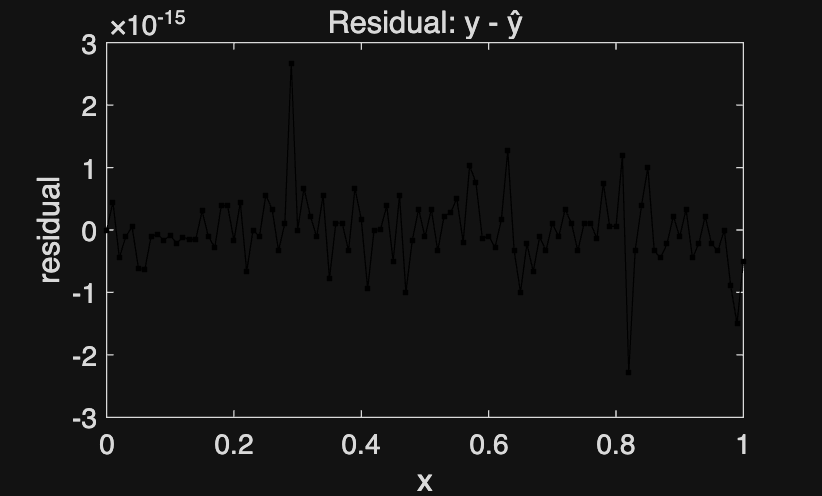


figure; grid on;
plot(x, res, 'k.-');
xlabel('x'); ylabel('residual');
title('Residual: y - ŷ');


fprintf('\nFinal fitted function:\n');


Final fitted function:


fprintf('f(x) = %.4e + (%.4e)*x + (%.4e)*cos(%.4f*pi*x) + (%.4e)*sin(%.4f*pi*x)\n', ...
        a0, a1, bc, 2*k, bs, 2*k);

f(x) = -7.0000e-01 + (1.0000e+00)*x + (-5.4530e-17)*cos(5.0000*pi*x) + (6.0000e-01)*sin(5.0000*pi*x)


Convert to amplitude–phase

w   = 2*pi*k;                 
A   = hypot(bc, bs);
phi = atan2(bs, bc);          
fprintf('Equivalent: f(x) = %.4e + (%.4e)*x + %.4e*cos(%.4f*x - %.4f)\n', ...
        a0, a1, A, w, phi);

Equivalent: f(x) = -7.0000e-01 + (1.0000e+00)*x + 6.0000e-01*cos(15.7080*x - 1.5708)


Error Metrics

res = y - yhat;
mse = mean(res.^2);
rmse = sqrt(mse);
R2  = 1 - sum(res.^2)/sum((y-mean(y)).^2);
fprintf('RMSE = %.4e,  MSE = %.4e,  R^2 = %.6f\n', rmse, mse, R2);

RMSE = 5.7755e-16,  MSE = 3.3357e-31,  R^2 = 1.000000
